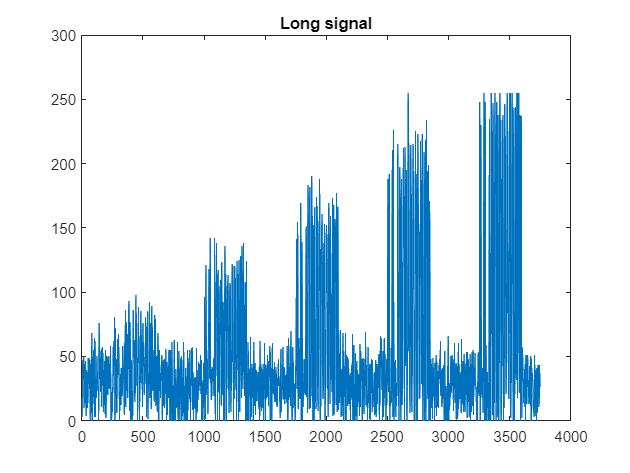

clear
load("tempNeigiamasRodiklisData.mat")

minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

dataSend = "101101110101010101011000111";
singleSigLength = 750;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
plot(ADCsignalLong)
title("Long signal")

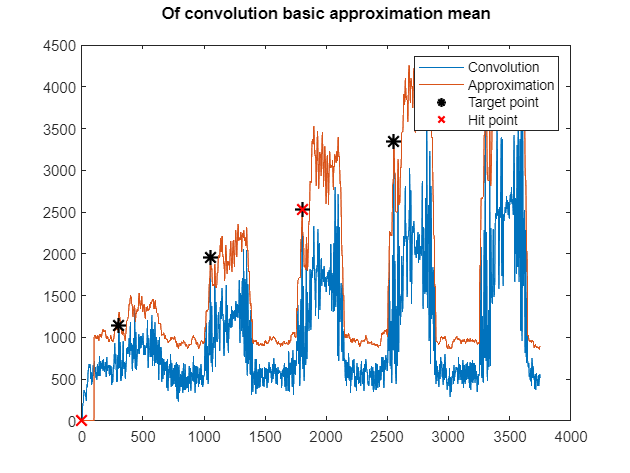

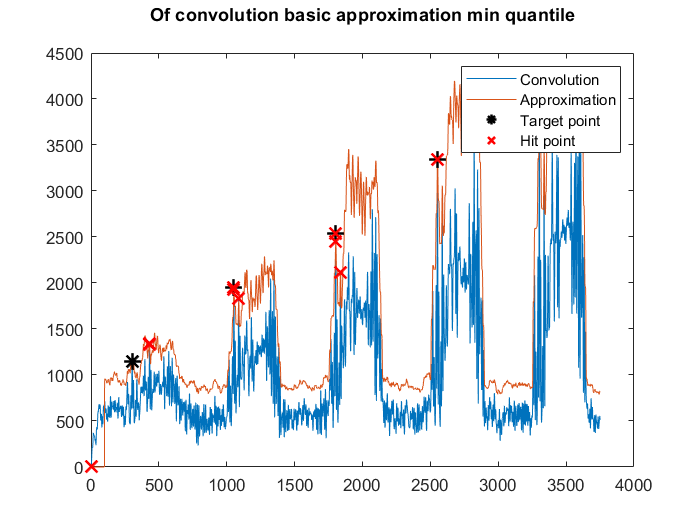

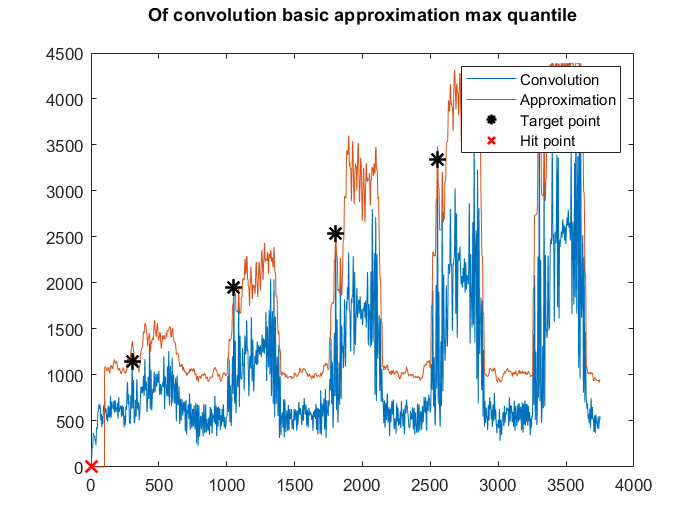

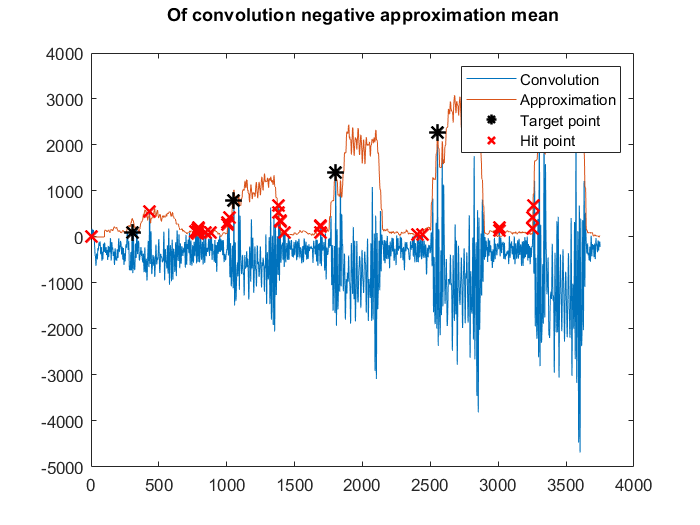

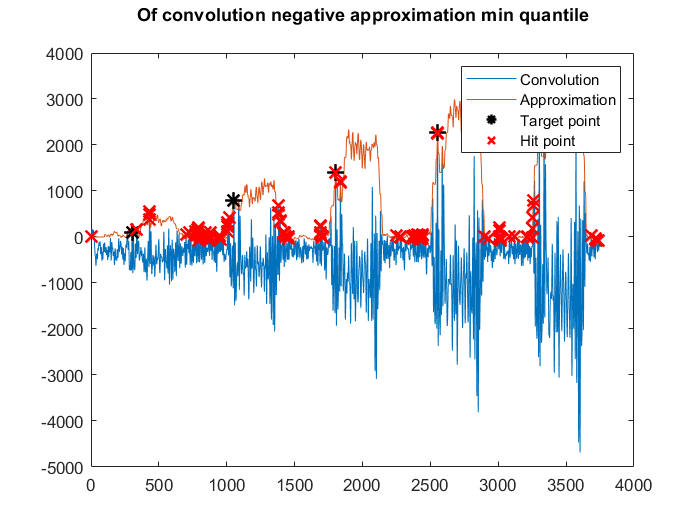

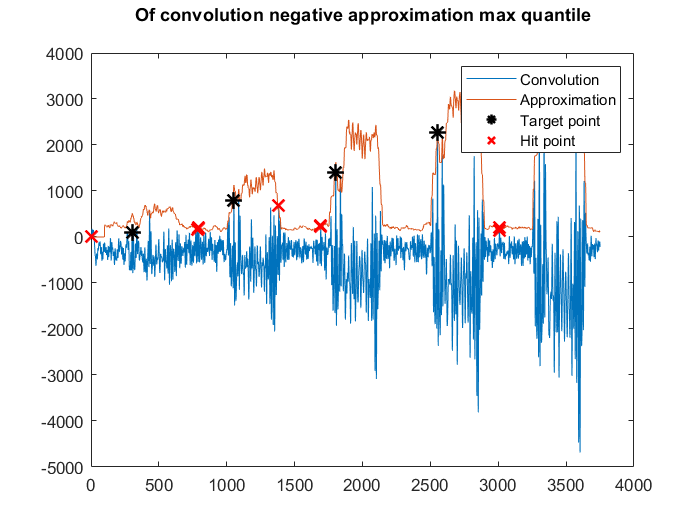

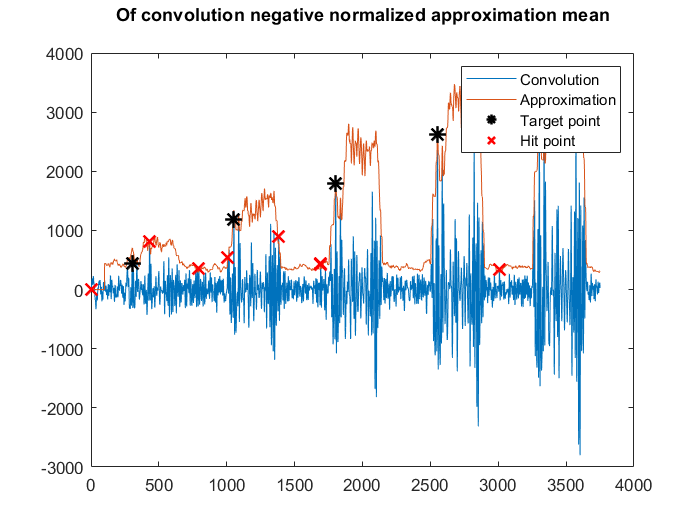

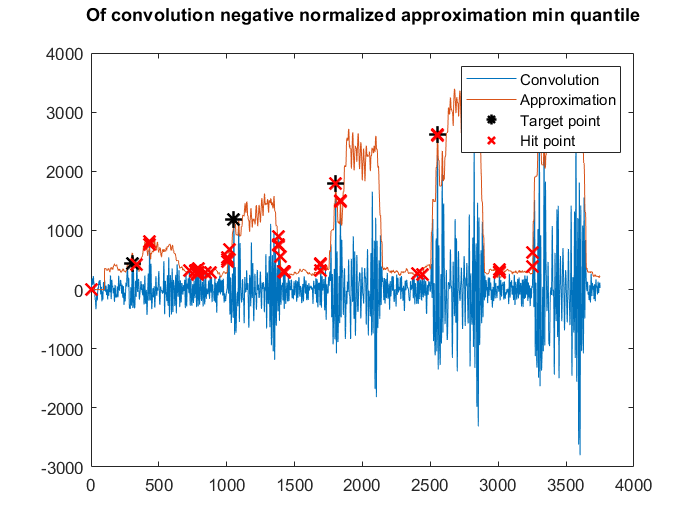

allMinimumEnergy = zeros(1, length(allApproximations));

allMinimumEnergy((ConvolutionEnum.extendedNormalized-1) * ApproximationEnum.last + ApproximationEnum.minQuantile) = 100000;

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
        if convTypes(convIndex).diffAmount == 0
            currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
        else %Is differentiated
            movedADCsignalLong = [zeros(1, convTypes(convIndex).diffAmount), ADCsignalLong];
            diffADCsignalLong = ADCsignalLong - movedADCsignalLong(1:length(ADCsignalLong));
            currentConvolution = GenerateConv(diffADCsignalLong, convTypes(convIndex).convPreambule);
        end
        
        coeficientAmount = length(allApproximations(approximationIndex).coeficients);
        windowLength = length(convTypes(convIndex).convPreambule);
        currentEnergy = zeros(1, length(ADCsignalLong));
        currentApproximation = zeros(1, length(ADCsignalLong));
        for i = 100:length(currentEnergy)
            energyMaxPoint = i;
            energyMinPoint = i - windowLength;
            currentEnergy(i) = sum(abs(ADCsignalLong(energyMinPoint : energyMaxPoint) .* ADCsignalLong(energyMinPoint : energyMaxPoint)));
            if(currentEnergy(i) <= allMinimumEnergy(approximationIndex))
                currentEnergy(i) = allMinimumEnergy(approximationIndex);
            end
            currentApproximation(i) = currentEnergy(i)^2*allApproximations(approximationIndex).coeficients(1)+currentEnergy(i)*allApproximations(approximationIndex).coeficients(2)+allApproximations(approximationIndex).coeficients(3);
        end
        hitPointsX = zeros(1, length(ADCsignalLong));
        hitPointsY = zeros(1, length(ADCsignalLong));
        hitPointsIndex = 1;
        for ii = 100:length(ADCsignalLong)
            if currentConvolution(ii) > currentApproximation(ii)
                hitPointsX(hitPointsIndex) = ii;
                hitPointsY(hitPointsIndex) = currentConvolution(ii);
                hitPointsIndex = hitPointsIndex + 1;
            end
        end
        hitPointsX = hitPointsX(1:hitPointsIndex);
        hitPointsY = hitPointsY(1:hitPointsIndex);
        targetPointsX = zeros(1, stepCount);
        targetPointsY = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + length(ADCsignal) * (ii-1);
            targetPointsY(ii) = currentConvolution(targetPointsX(ii));
        end

        figure
        plot(currentConvolution, 'DisplayName', "Convolution")
        hold on
        %plot(currentEnergy, 'DisplayName', "Energy")
        plot(currentApproximation, 'DisplayName', "Approximation")
        scatter(targetPointsX, targetPointsY,100,"*", "black",'LineWidth', 1.5, 'DisplayName', "Target point")
        scatter(hitPointsX, hitPointsY,100,"x", "red",'LineWidth', 1.5, 'DisplayName', "Hit point")
        hold off
        title(sprintf("Of convolution %s approximation %s\n", convTypes(convIndex).name, allApproximations(approximationIndex).name));
        legend
    end
end

clear
load("tempNeigiamasRodiklisData.mat")

testAmount = 10;
minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

dataSend = "101101110101010101011000111";
singleSigLength = 750;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);

testHitsCorrect = zeros(1, length(allApproximations));
testHitsFailed = zeros(1, length(allApproximations));
testAllHits = zeros(length(allApproximations), singleSigLength * stepCount);
testAllHitsAmplitude = zeros(length(allApproximations), singleSigLength * stepCount, testAmount);
testAllHitsEnergy = zeros(length(allApproximations), singleSigLength * stepCount, testAmount);

for testIndex = 1:testAmount
    for generuojama_amplitude_index = 1:stepCount
        generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generatedAmplitude);
        copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
        copyIndexLast = singleSigLength*(generuojama_amplitude_index);
        ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
        idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
    end
    for convIndex = 1:uint32(ConvolutionEnum.last)
        targetPointsX = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + singleSigLength * (ii-1);
        end
        for approxIndex = 1:uint32(ApproximationEnum.last)
            approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
            if convTypes(convIndex).diffAmount == 0
                currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
            else %Is differentiated
                movedADCsignalLong = [zeros(1, convTypes(convIndex).diffAmount), ADCsignalLong];
                diffADCsignalLong = ADCsignalLong - movedADCsignalLong(1:length(ADCsignalLong));
                currentConvolution = GenerateConv(diffADCsignalLong, convTypes(convIndex).convPreambule);
            end
            coeficientAmount = length(allApproximations(approximationIndex).coeficients);
            windowLength = length(convTypes(convIndex).convPreambule);
            currentEnergy = zeros(1, length(ADCsignalLong));
            currentApproximation = zeros(1, length(ADCsignalLong));
            for i = 100:length(currentEnergy)
                energyMaxPoint = i;
                energyMinPoint = i - windowLength;
                currentEnergy(i) = sum(abs(ADCsignalLong(energyMinPoint : energyMaxPoint) .* ADCsignalLong(energyMinPoint : energyMaxPoint)));
                currentApproximation(i) = currentEnergy(i)^2*allApproximations(approximationIndex).coeficients(1)+currentEnergy(i)*allApproximations(approximationIndex).coeficients(2)+allApproximations(approximationIndex).coeficients(3);
            end

            for ii = 100:length(ADCsignalLong) %Ignore signal until 100 samples in
                if currentConvolution(ii) > currentApproximation(ii)
                    if ismember(ii, targetPointsX)
                        testHitsCorrect(approximationIndex) = testHitsCorrect(approximationIndex) + 1;
                    else
                        testHitsFailed(approximationIndex) = testHitsFailed(approximationIndex) + 1;
                    end
                    testAllHits(approximationIndex, ii) = testAllHits(approximationIndex, ii) + 1;
                    testAllHitsAmplitude(approximationIndex, ii, testAllHits(approximationIndex, ii)) = currentConvolution(ii);
                    testAllHitsEnergy(approximationIndex, ii, testAllHits(approximationIndex, ii)) = currentEnergy(ii);
                end
            end
        end
    end
end

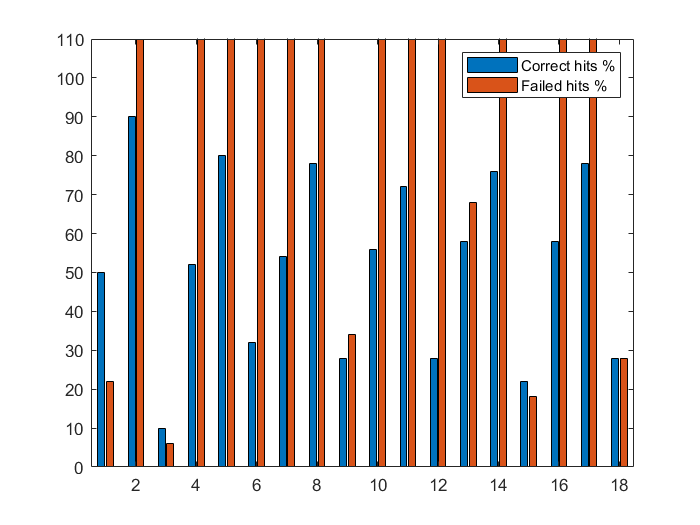

allStats = zeros(2, length(allApproximations));
allStats(1, :) = testHitsCorrect / (testAmount * stepCount) * 100;
allStats(2, :) = testHitsFailed / (testAmount * stepCount) * 100;
bar(transpose(allStats))
ylim([0, 110])

legend("Correct hits %", "Failed hits %")

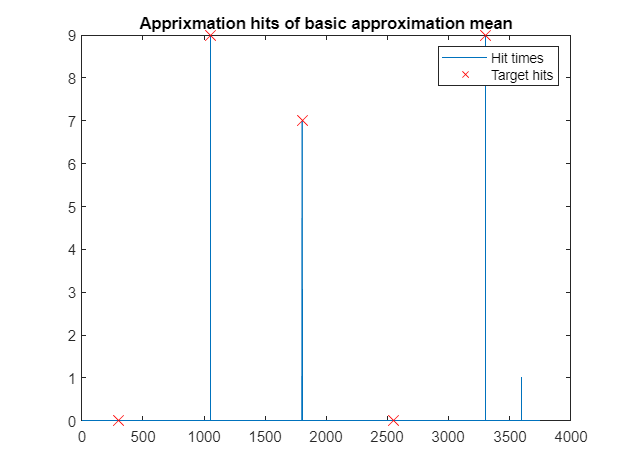

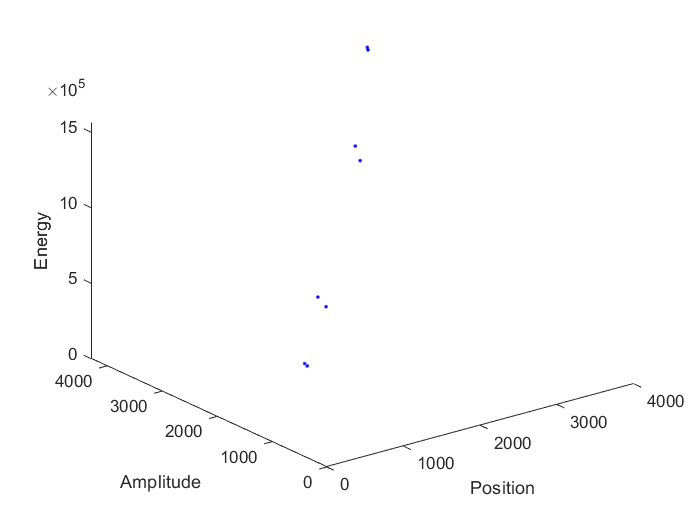

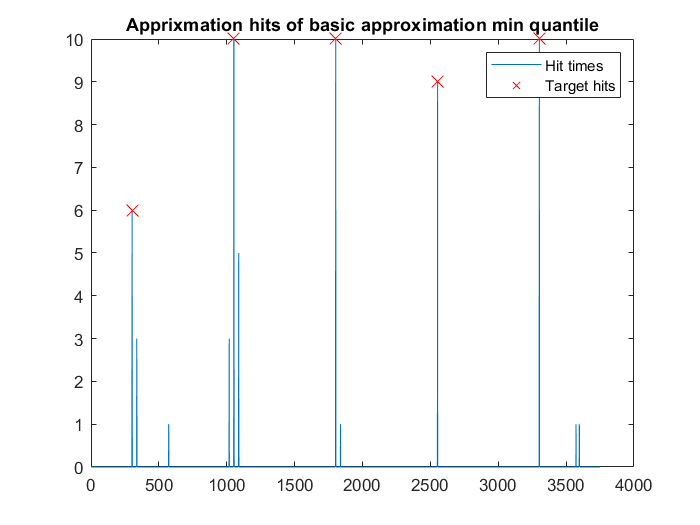

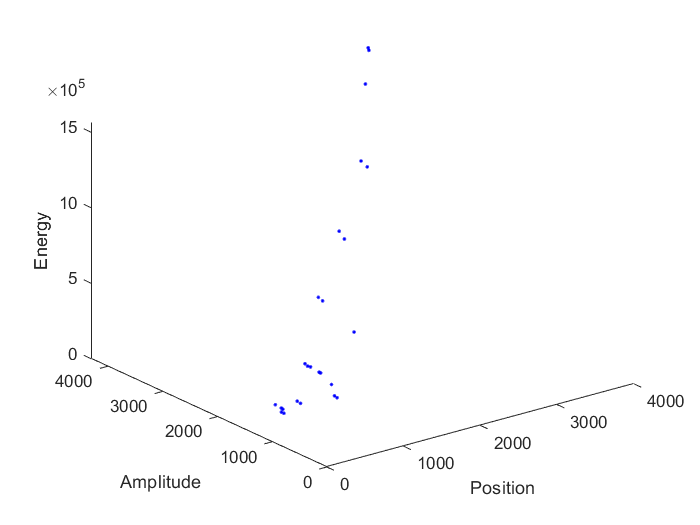

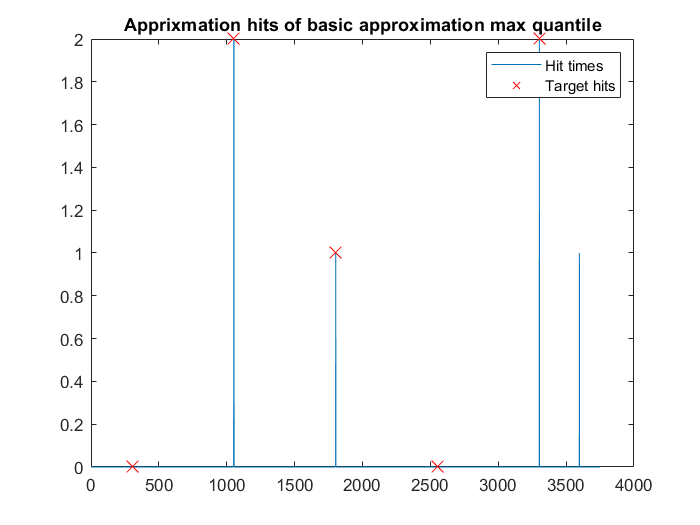

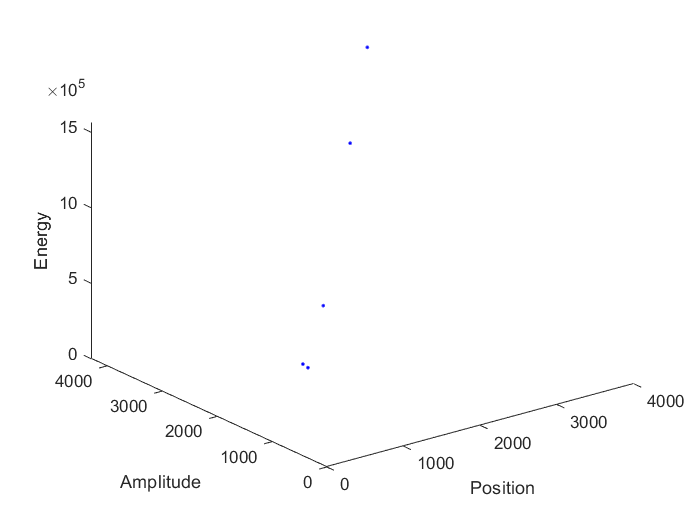

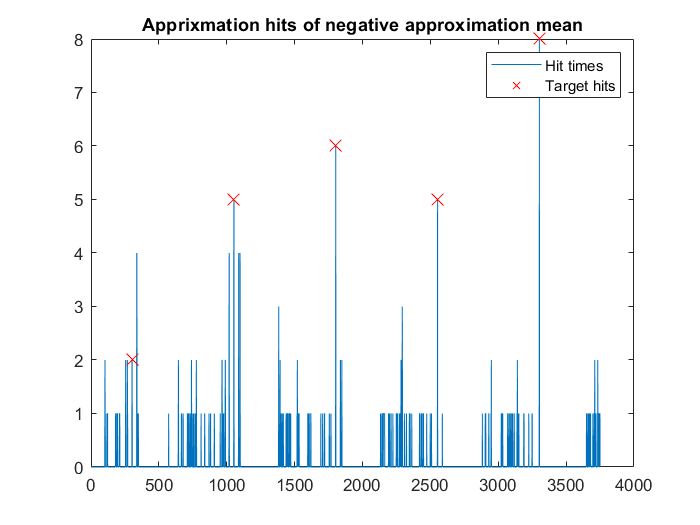

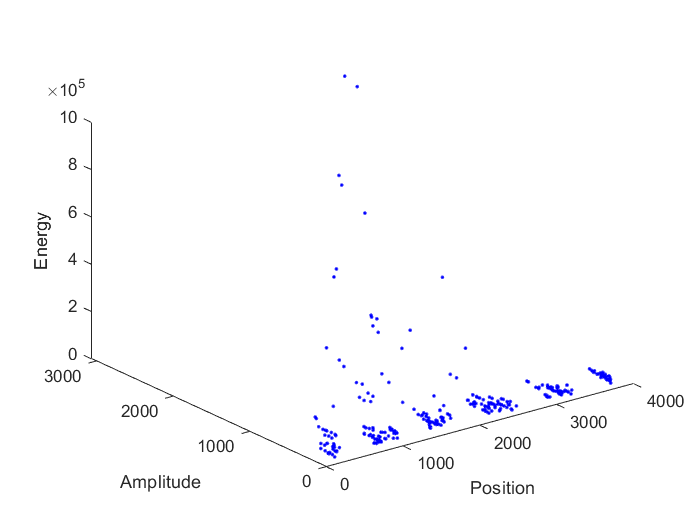

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
        targetPointsX = zeros(1, stepCount);
        targetPointsY = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + singleSigLength * (ii-1);
            targetPointsY(ii) = testAllHits(approximationIndex, targetPointsX(ii));
        end

        figure
        plot(testAllHits(approximationIndex, :), 'DisplayName', "Hit times")
        hold on
        scatter(targetPointsX, targetPointsY,100, 'x','red', 'DisplayName', "Target hits")
        hold off
        title(sprintf("Apprixmation hits of %s approximation %s", convTypes(convIndex).name, allApproximations(approximationIndex).name))
        legend

        figure
        plot3(0, 0, 0)
        hold on
        for i = 1:singleSigLength * stepCount
            for ii = 1:10:testAllHits(approximationIndex, i)
                plot3(i, testAllHitsAmplitude(approximationIndex, i, ii),testAllHitsEnergy(approximationIndex, i, ii), '.',"Color", "b")
            end
        end
        hold off
        xlabel("Position")
        ylabel("Amplitude")
        zlabel("Energy")
    end
end